# Hopper dynamics. Quaternion Plant. 21.03.2025

#### To see at scheme and equations, look at 6DoF_v4_symbolic.mlx

clc; clear all; close all;

SimulinkOpen = false;
disturbOn = false;
GravityCompansation = true;
Euler_Angles = true;

## Generate trajectory (Earth Frame)

run("Generate_trajectory.m")

gg = 9.8065;            % G-Force value
Lg = 1 / gg;            % Inverse G-force value
G0 = [0; -gg; 0];       % G-Force vector in Earth Frame
Tjet = 32;
Troll = 3;
Tpy = 3;
e_y = 0;
e_z = 0;
l_2 = 0.3608544;    % 0.403;
l_3 = 0.3608544;    % 0.403;
l_4 = 0.3608544;    % 0.403;
l_5 = 0.3608544;    % 0.403;
l_6 = 0.2717;       % 0.263
l_7 = 0.2717;       % 0.263
l_8 = 0.2717;       % 0.263
l_9 = 0.2717;       % 0.263
d_2 = 0.305;    % 0.039;
d_3 = 0.305;    % 0.039;
d_4 = 0.305;    % 0.039;
d_5 = 0.305;    % 0.039;
d_6 = 0.2739;   %-0.018;
d_7 = 0.2739;
d_8 = 0.2739;
d_9 = 0.2739;
action_params = [
%     Thrust  ex ey   ez    Froll Fpitch Fyaw Lphi Lpitch Lyaw
     Tjet,    0, e_y, e_z,    0,  0,   0,   0,  0,  0;
     Troll, l_2, d_2,   0,  -45,  90,  0,   45, 90, 0;
     Troll, l_3, d_3,   0,   45,  90,  0,  -45, 90, 0;
     Troll, l_4, d_4,   0,  135,  90,  0, -135, 90, 0;
     Troll, l_5, d_5,   0, -135,  90,  0,  135, 90, 0;
     Tpy,   l_6, d_6,   0,    0,  0,   0,   90, 90, 0;
     Tpy,   l_7, d_7,   0,    0,  0,   0,    0, 90, 0;
     Tpy,   l_8, d_8,   0,    0,  0,   0,  -90, 90, 0;
     Tpy,   l_9, d_9,   0,    0,  0,   0,  180, 90, 0
];
clear e_y e_z l_2 l_3 l_4 l_5 l_6 l_7 l_8 l_9 d_2 d_3 d_4 d_5 d_6 d_7 d_8 d_9;
geometry = action_params(:, 2:end);

%% Hopper's Moment of Inertia from Solidworks
tensors =  1e-9 * [
            2686253579.02, 650492741.40, 2687752194.18, -5482732.37, -691010.46, -2534148.08;
            2655165676.51, 642221197.41, 2656665844.71, -5067466.66, -698825.09, -2075573.42;
            2622453318.66, 633948606.77, 2623955143.39, -4624528.20, -707160.48, -1586439.96;
            2587948531.42, 625674861.26, 2589452126.87, -4151055.54, -716070.47, -1063587.82;
            2551459355.20, 617399837.21, 2552964847.80, -3643778.62, -725616.60, -503405.90;
            2512765405.26, 609123392.61, 2514272935.47, -3098943.17, -735869.52, 98251.60
];

mass = 1e-3 * [
        25610.09, 24810.09, 24010.09, 23210.09, 22410.09, 21610.09;
];
rcgs = 1e-3 * [
	    -1.84, 666.97, -1.53;
        -1.74, 661.43, -1.43;
        -1.64, 655.52, -1.32;
        -1.54, 649.21, -1.20;
        -1.42, 642.44, -1.07;
        -1.30, 635.17, -0.93
    ];
% Define sample 3x3 tensors at different time steps
Tensors = cat(3, RotateTensor(Vector2Tensor(tensors(1,:)), [0, pi/2, 0]), ...
                 RotateTensor(Vector2Tensor(tensors(2,:)), [0, pi/2, 0]), ...
                 RotateTensor(Vector2Tensor(tensors(3,:)), [0, pi/2, 0]), ...
                 RotateTensor(Vector2Tensor(tensors(4,:)), [0, pi/2, 0]), ...
                 RotateTensor(Vector2Tensor(tensors(5,:)), [0, pi/2, 0]), ...
                 RotateTensor(Vector2Tensor(tensors(6,:)), [0, pi/2, 0]) ...
               );
clear tensors;

m_max = mass(1);                    % maximum mass
m_dry = mass(end);                  % minimum mass
fuel_capacity = 4;                  % Full fuel capacity
m_fuel = 4;                         % mass of fuel
m_full = m_dry + fuel_capacity;     % mass of filled hopper
m = m_dry + m_fuel;                 % current or initial mass


geometry(2:5, 1) = ones(4,1) * rcgs(1, 2);

% Central tensor inertia moment 
Js = DiagTensorInertia(tensor_interpolation(m, mass, Tensors));
% Tensor of Inertia for dry hopper
Js0 = DiagTensorInertia(tensor_interpolation(m_dry, mass, Tensors));

% jet rotor mass inertia
Jrotx = 9e-3; Jroty = 1e-2; Jrotz = 1e-2;
Jrot = diag([Jrotx, Jroty, Jrotz]);
params_rotor = [Jrotx, Jroty, Jrotz];

% Tensor Inertia Components
Jxx = Js(1,1); Jyy = Js(2,2); Jzz = Js(3,3);


Mass = diag([m, m, m]);
Thrust = 45;                                % Maximum Thrust, kg
mdot_max = 17.7 * 1e-3 * Tjet / Thrust;     % kg/s, max consumption
Fmax = Tjet * gg;                           % N, 

%% Frequency 
n_max = 90000;               % rpm
wn_max = pi * n_max / 30;    % rad/s

beta = mdot_max / Fmax;     % mass consumption to thrust ratio
gamma = wn_max / Fmax;      % frequency to thrust ratio

rho = 1.2754;               % air density

% Damphers
c_v = 0.1;      % Linear
c_w = 0.01;     % Angular

% Damping matrix
Cv = diag([c_v, c_v, c_v]);
Cw = diag([c_w, c_w, c_w]);


% Center of mass
r_cg = rcgs(1, :);

[Hf, Hm] = ComponentForForces(geometry, rcgs(1,:))

Hf =     1.0000    0.0000    0.0000    0.0000    0.0000    1.0000    1.0000    1.0000    1.0000
         0    0.7071    0.7071   -0.7071   -0.7071         0         0         0         0
         0   -0.7071    0.7071    0.7071   -0.7071         0         0         0         0


Hm =          0   -0.1964    0.1943   -1.1375    1.1397         0         0         0         0
    0.0015    0.2170   -0.2170   -0.2170    0.2170    0.2732    0.0015   -0.2702    0.0015
    0.6670    0.2170    0.2170   -0.2170   -0.2170    0.6670    0.3953    0.6670    0.9387


%% Remove unnessary data
clear c_v c_w Thrust mdot_max Fmax wn_max Fmax;
% clear Jxx Jyy Jzz;
clear Jrotx Jroty Jrotz;

## Show unit force matrices

HH = [Hf; Hm];
HH = HH(:, 2:end)

HH =     0.0000    0.0000    0.0000    0.0000    1.0000    1.0000    1.0000    1.0000
    0.7071    0.7071   -0.7071   -0.7071         0         0         0         0
   -0.7071    0.7071    0.7071   -0.7071         0         0         0         0
   -0.1964    0.1943   -1.1375    1.1397         0         0         0         0
    0.2170   -0.2170   -0.2170    0.2170    0.2732    0.0015   -0.2702    0.0015
    0.2170    0.2170   -0.2170   -0.2170    0.6670    0.3953    0.6670    0.9387


## Initial conditions

r = [0; 0; 0];              % position
v = [0; 0; 0];              % velocity
a = [0; pi/2.; 0];          % attitude [yaw, pitch, roll]
a1 = [pi/2; 0; 0];          % [pitch, yaw, roll] -> change the sequense of rotation
q = eul2quat(a1', 'ZYX')';  % quaternion
w = [0; 0; 0];              % angular velocity
mu = [m];                   % mass
% General State vector
s0 = [r; v; a; w];          % State Space vector [pos, vel, eul, rot]
xIC = [r; v; a; w];         % initial condition for Simulink model
sm = [r; v; q; w; mu];      % State Space vector with Mass
sr = [r; v];
sa = [q; w];                % State Space vector for rotation

## Linear system. Plant

### Translational matrix A

Mass = diag([m, m, m]);
% Massinv = inv(Mass);
A11 = zeros(3,3);
A12 = eye(3,3);
A21 = zeros(3,3);
A22 = -skew(w) + Mass \ (-Cv); % + Nrot * G; for linear system exclude gravity (to make system Linear)

At = [A11, A12;
      A21, A22]

At =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
         0         0         0   -0.0039         0         0
         0         0         0         0   -0.0039         0
         0         0         0         0         0   -0.0039


### Rotational Matrix A

A33 = zeros(3,3);
A43 = zeros(3,3);
A34 = Tw(a);
A44 = Js \ (-skew(w) * Js - Cw);
Ar = [A33, A34;
      A43, A44];
Ar

Ar =          0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000
         0         0         0         0    1.0000         0
         0         0         0   -0.0154         0         0
         0         0         0         0   -0.0037         0
         0         0         0         0         0   -0.0037


### Full Dynamic Matrix A

As = [At, zeros(6,6);
     zeros(6,6), Ar];
As

As =          0         0         0    1.0000         0         0         0         0         0         0         0         0
         0         0         0         0    1.0000         0         0         0         0         0         0         0
         0         0         0         0         0    1.0000         0         0         0         0         0         0
         0         0         0   -0.0039         0         0         0         0         0         0         0         0
         0         0         0         0   -0.0039         0         0         0         0         0         0         0
         0         0         0         0         0   -0.0039         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0    1.0000         0         0
         0         0         0         0         0         0         0         0         0         0         0    1.0000
         0         0       

%% Remove unnessary parameters
clear A11 A12 A21 A22 A33 A34 A43 A44 At Ar;

### Control Matrix B

#### Translational matrix B

B11 = zeros(3, 9);
B21 = Mass \ Hf;
Bt = [B11;
      B21];
Bt

Bt =          0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
    0.0390    0.0000    0.0000    0.0000    0.0000    0.0390    0.0390    0.0390    0.0390
         0    0.0276    0.0276   -0.0276   -0.0276         0         0         0         0
         0   -0.0276    0.0276    0.0276   -0.0276         0         0         0         0


#### Rotational Matrix B

B31 = zeros(3,9);
B41 = Js \ Hm;
Br = [B31;
      B41];
Br

Br =          0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0    0.1038   -0.1072   -1.3429    1.3462         0         0         0         0
    0.0006    0.0108   -0.0108   -0.0108    0.0108    0.0985    0.0006   -0.0973    0.0006
    0.2482    0.0107    0.0107   -0.0107   -0.0107    0.2482    0.1503    0.2482    0.3460


#### Full Control Matrix B

Bs = [Bt; Br]

Bs =          0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
    0.0390    0.0000    0.0000    0.0000    0.0000    0.0390    0.0390    0.0390    0.0390
         0    0.0276    0.0276   -0.0276   -0.0276         0         0         0         0
         0   -0.0276    0.0276    0.0276   -0.0276         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0    0.1038   -0.1072   -1.3429    1.3462         0         0         0         0


%% Remove unnessary parameters
clear B11 B21 B31 B41 Bt Br; 

### Observer matrices

Cs = eye(12, 12);
Ds = zeros(12, 9);

### System Analysis

#### Controlability

Co = ctrb(As, Bs);
rank_Co = rank(Co)

rank_Co = 12

#### Observability

Ob = obsv(As, Cs);
rank_Ob = rank(Ob)

rank_Ob = 12

### LQR

%% Deviation Penalty
% Qs = diag([10, 10, 10, ...       % Position
%     100, 100, 100 ...                  % Linear velocity    
%     1, 1, 1, ...                % Euler's Angles
%     1, 1, 1]); % ...                % Angular velocity
% %% Control Penalty
% Rs = diag([0.001, ...                % Jet
%     0.5, 0.5, 0.5, 0.5, ...     % Roll Forces
%     1, 1, 1, 1]);           % Pitch and Roll

Qs = diag([100, 100, 100, ...       % Position
    50, 50, 50 ...                  % Linear velocity    
    20, 20, 20, ...                % Euler's Angles
    2, 2, 2]); % ...                % Angular velocity
%% Control Penalty
Rs = diag([0.001, ...                % Jet
    0.5, 0.5, 0.5, 0.5, ...     % Roll Forces
    1, 1, 1, 1]);           % Pitch and Roll
K_lqrq = lqr(As, Bs, Qs, Rs)

K_lqrq =   115.0484   -1.5109    0.0035   82.2033   -2.0265    0.0047   -0.0000  131.4250    0.3016   -0.0000    0.1229   53.5668
   -0.2887    7.0570   -9.9727   -0.3651   12.3044  -20.9075    0.1032    0.0660    0.3424   -0.2778    0.3346    0.0609
   -0.2874    7.0703    9.9626   -0.3634   12.3438   20.8960   -0.1137    0.0673   -0.3429    0.2731   -0.3350    0.0621
    0.2887   -7.0804   -0.2400    0.3651  -12.3553   -1.2592   -4.4655   -0.0668   -0.0104   -2.3240    0.0090   -0.0617
    0.2874   -7.0468    0.2501    0.3634  -12.2929    1.2707    4.4760   -0.0665    0.0109    2.3288   -0.0085   -0.0613
    0.1000   -0.0010    0.5412    0.0337   -0.0011    1.5889   -0.0134    0.1268    3.1533   -0.0136    5.7386    0.0481
    6.6932    0.3211    0.0005   21.2078    1.1908    0.0009   -0.0000   -1.0195    0.0049   -0.0000    0.0056   -3.2917
    0.1301   -0.0020   -0.5412    0.1307   -0.0029   -1.5888    0.0134    0.1360   -3.1527    0.0136   -5.7383    0.0591
   -6.4631   -0.3241   

## Simulation

### Open Loop System

Ps = ss(As, Bs, Cs, Ds);

### Closed-loop system (Alternative Approach)

% A_cl = As - Bs * K_lqrq; % Closed-loop state matrix
% B_cl = Bs;                  % Closed-loop input matrix
% C_cl = Cs;                  % Closed-loop output matrix
% D_cl = Ds;                  % Closed-loop feedthrough matrix

% Create the closed-loop state-space system
% Gcl2 = ss(A_cl, B_cl, C_cl, D_cl);
Gcl = feedback(Ps * K_lqrq, eye(12));
sys_poles = pole(Gcl);
sys_poles

sys_poles = 1.0e+02 *

  -1.1156 + 0.0000i
  -0.3815 + 0.0000i
  -0.0195 + 0.0000i
  -0.0045 + 0.0022i
  -0.0045 - 0.0022i
  -0.0020 + 0.0017i
  -0.0020 - 0.0017i
  -0.0033 + 0.0022i
  -0.0033 - 0.0022i
  -0.0032 + 0.0000i


% rq0 = [0, 0, 0, 0, 0, 0, 0.7071, 0,      0.7071,  0,      0, 0, 0];
% xq0 = [0, 0, 0, 0, 0, 0, 0.7191, 0.0188, 0.6944, -0.0182, 0, 0, 0];
%    30.0000

### Initial value problem (IVP)

%% Initial Condition (IC)
x0 = zeros(1, 14);
y0 = zeros(1, 13);
% x0(7) = deg2rad(3);                                     % Initial Roll Deviation
% x0(8) = deg2rad(0);                                    % Initial Pitch Value
% initial attitude deviation
init_yaw = 0;
init_pitch = 90;
init_roll = 3;
quat0 = eul2Quat(deg2rad([init_roll, init_pitch, init_yaw]));
x0(7:10) = quat0;                                       % Initial quaternion
x0(14) = m;
y0(7:9) = deg2rad([init_roll, init_pitch, init_yaw]);
y0(13) = m;
% x0 = x0;
% Reference Vector (does not contain mass)
ref_yaw = 0;
ref_pitch = 90;
ref_roll = 0;
quat_ref = eul2Quat(deg2rad([ref_roll, ref_pitch, ref_yaw]));
%      x  y  z    vx  vy  vz q0 q1 q2 q3 wx wy wz
ref_quat = [1; 0; 0;  0.1;  0;  0; 0; 0; 0; 0; 0; 0; 0];         % Reference vector
ref_quat(7:10) = quat_ref';                                  % Reference quaternions
ref_eul = [1; 0; 0;  0;  0;  0; 0; pi/2; 0; 0; 0; 0];
% Time span
dtau = 0.01;                                        % Time step
Tf = 30;                                            % Final time
T = 0:dtau:Tf;

%               dFx  dFy  dFz dMx dMy dMz
disturbances = [0;    0;   0;  0;  0;  0];      % either constants or functions
k_quat = 1;
%% For Jdot calculation
Jo = DiagTensorInertia(Tensors(:,:, 1));
Jf = DiagTensorInertia(Tensors(:,:, end));
mo = mass(1);
mf = mass(end);
Jdot_coeff = (Jo - Jf) / (mo - mf);
gc = 0; %GravityCompansation;
parameters = [Tensor2Vector(Js)'; Cv(1,1); Cv(2,2); Cv(3,3); Cw(1,1); Cw(2,2); Cw(3,3); gg; beta; gamma; rho; diag(Jdot_coeff); k_quat; gc; mo];

## Simulation

% Define ODE function
ode_hopper = @(t, x) NL_HopperDyn_ODE(t, x, ref_eul, disturbances, Tensors, mass, parameters, K_lqrq, [Hf; Hm]);

### Solving

[t, z] = ode45(ode_hopper, T, y0);

## Control Forces

Fc = zeros(size(K_lqrq, 1), length(T));
Fc2 = zeros(size(K_lqrq, 1), length(T));
for i=1:length(T)
    xref = ref_eul;
    Fc(:, i) = -K_lqrq * (z(i, 1:12)' - xref);
    Fc2(:, i) = Fc(:, i);
    Fcomp = z(i, 13) * Nw(z(i, 7:9)) * G0;
    Fc2(1, i) = Fc2(1, i) - Fcomp(1);
end
Fc = Lg * Fc;
Fc2 = Lg * Fc2;

## Euler's Angles (from Quaternions)

euls = zeros(length(T), 3);
euls2 = zeros(length(T), 3);
eul_prev = z(1, 7:9);
euls(1,:) = eul_prev;
euls2(1,:) = eul_prev;
for i=2:length(T)
%     euls(i, :) = quat_to_euler_continuous(z(i, 7:10)', eul_prev);
    euls(i, :) = z(i, 7:9);
    deul = z(i, 7:9) - eul_prev;
    euls2(i, :) = euls2(i-1, :) + quat2eul(eul2quat(deul, 'ZYX'));
    eul_prev = euls2(i,:);
end

## Plot Results

### Translational

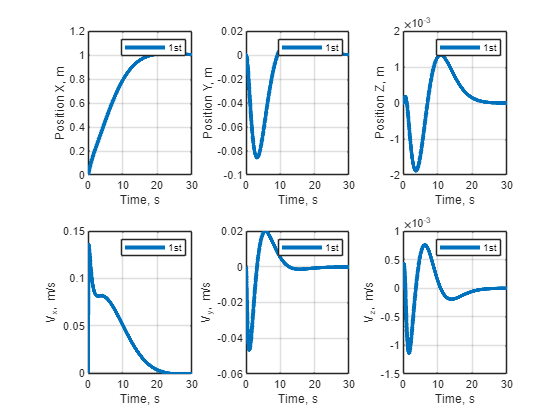

% Reference trajectory
figure;

subplot(2,3,1);
plot(T, z(:,1)); grid;
xlabel('Time, s');
ylabel('Position X, m');
legend({'1st'});

subplot(2,3,2);
plot(T, z(:,2)); grid;
xlabel('Time, s');
ylabel('Position Y, m');
% legend({'Const', 'Traj'});
legend({'1st'});

subplot(2,3,3);
plot(T, z(:,3)); grid;
xlabel('Time, s');
ylabel('Position Z, m');
% legend({'Const', 'Traj'});
legend({'1st'});

subplot(2,3,4);
plot(T, z(:,4)); grid;
xlabel('Time, s');
ylabel('V_x, m/s');
% legend({'Const', 'Traj'});
legend({'1st'});

subplot(2,3,5);
plot(T, z(:,5)); grid;
xlabel('Time, s');
ylabel('V_y, m/s');
% legend({'Const', 'Traj'});
legend({'1st'});

subplot(2,3,6);
plot(T, z(:,6)); grid;
xlabel('Time, s');
ylabel('V_z, m/s');
% legend({'Const', 'Traj'});
legend({'1st'});

set(groot, 'DefaultFigurePosition', [100, 100, 5000, 5000]);
% set(groot, 'DefaultFigurePosition', 'factory');    % use to reset size
set(findall(gcf,'type','line'),'linewidth', 3);

### Rotational

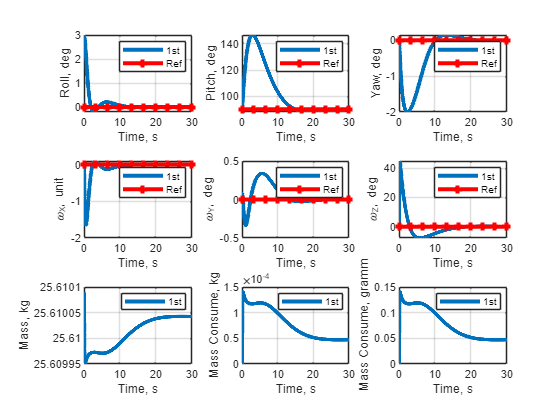

tspan = linspace(T(1), T(end), 10); 
mones = ones(1,10);
figure;

subplot(3,3,1);
plot(T, rad2deg(z(:, 7)), tspan, mones* rad2deg(ref_eul(7)), 'r+-'); grid;
xlabel('Time, s');
ylabel('Roll, deg');
legend({'1st', 'Ref'});

subplot(3,3,2);
plot(T, rad2deg(z(:,8)), tspan, mones* rad2deg(ref_eul(8)), 'r+-'); grid;
xlabel('Time, s');
ylabel('Pitch, deg');
% legend({'Const', 'Traj'});
legend({'1st', 'Ref'});

subplot(3,3,3);
plot(T, rad2deg(z(:, 9)), tspan, mones* rad2deg(ref_eul(9)), 'r+-'); grid;
xlabel('Time, s');
ylabel('Yaw, deg');
% legend({'Const', 'Traj'});
legend({'1st', 'Ref'});

subplot(3,3,4);
plot(T, rad2deg(z(:,10)), tspan, mones* rad2deg(ref_eul(10)), 'r+-'); grid;
xlabel('Time, s');
ylabel('\omega_X, unit');
% legend({'Const', 'Traj'});
legend({'1st', 'Ref'});

% Euler's Rotation
subplot(3,3,5);
plot(T, rad2deg(z(:,11)), tspan, mones*rad2deg(ref_eul(11)), 'r+-'); grid;
xlabel('Time, s');
ylabel('\omega_Y, deg');
% legend({'Const', 'Traj'});
legend({'1st', 'Ref'});

subplot(3,3,6);
plot(T, rad2deg(z(:, 12)), tspan, mones*rad2deg(ref_eul(12)), 'r+-'); grid;
xlabel('Time, s');
ylabel('\omega_Z, deg');
% legend({'Const', 'Traj'});
legend({'1st', 'Ref'});


subplot(3,3,7);
plot(T, z(:,13)); grid;
xlabel('Time, s');
ylabel('Mass, kg');
% legend({'Const', 'Traj'});
legend({'1st'});

subplot(3,3,8);
plot(T, m - z(:, 13)); grid;
xlabel('Time, s');
ylabel('Mass Consume, kg');
% legend({'Const', 'Traj'});
legend({'1st'});

subplot(3,3,9);
plot(T, 1e3 * (m - z(:, 13))); grid;
xlabel('Time, s');
ylabel('Mass Consume, gramm');
% legend({'Const', 'Traj'});
legend({'1st'});

set(groot, 'DefaultFigurePosition', [50, 50, 2000, 2000]);
% set(groot, 'DefaultFigurePosition', 'factory');    % use to reset size
set(findall(gcf,'type','line'),'linewidth', 3);

### Forces

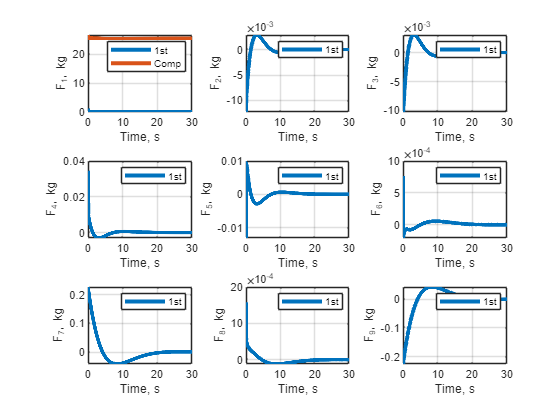

figure;

subplot(3,3,1);
plot(T, Fc(1,:), T, Fc2(1,:)); grid;
xlabel('Time, s');
ylabel('F_1, kg');
legend({'1st', 'Comp'});

subplot(3,3,2);
plot(T, Fc(2,:)); grid;
xlabel('Time, s');
ylabel('F_2, kg');
legend({'1st'});

subplot(3,3,3);
plot(T, Fc(3,:)); grid;
xlabel('Time, s');
ylabel('F_3, kg');
legend({'1st'});

subplot(3,3,4);
plot(T, Fc(4,:)); grid;
xlabel('Time, s');
ylabel('F_4, kg');
legend({'1st'});

subplot(3,3,5);
plot(T, Fc(5,:)); grid;
xlabel('Time, s');
ylabel('F_5, kg');
legend({'1st'});

subplot(3,3,6);
plot(T, Fc(6,:)); grid;
xlabel('Time, s');
ylabel('F_6, kg');
legend({'1st'});

subplot(3,3,7);
plot(T, Fc(7,:)); grid;
xlabel('Time, s');
ylabel('F_7, kg');
legend({'1st'});

subplot(3,3,8);
plot(T, Fc(8,:)); grid;
xlabel('Time, s');
ylabel('F_8, kg');
legend({'1st'});

subplot(3,3,9);
plot(T, Fc(9,:)); grid;
xlabel('Time, s');
ylabel('F_9, kg');
legend({'1st'});


set(groot, 'DefaultFigurePosition', [50, 50, 1500, 1000]);
% set(groot, 'DefaultFigurePosition', 'factory');    % use to reset size
set(findall(gcf,'type','line'),'linewidth', 3);

### Force projection

Forces = Hf * Fc;
Forces2 = Hf * Fc2;
Moments = Hm * Fc;

### Plot Force's Projections

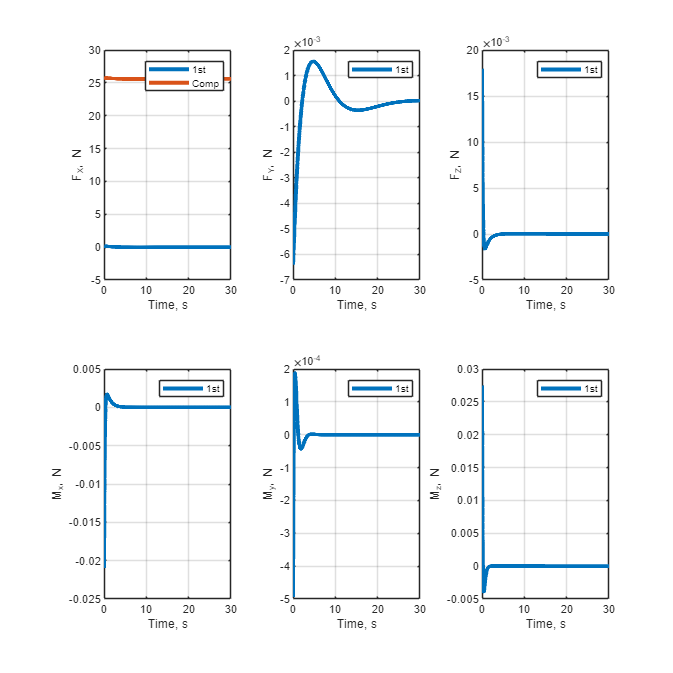

figure;

subplot(2,3,1);
plot(T, Forces(1,:), T, Forces2(1,:)); grid;
xlabel('Time, s');
ylabel('F_X, N');
legend({'1st', 'Comp'});

subplot(2,3,2);
plot(T, Forces(2,:)); grid;
xlabel('Time, s');
ylabel('F_Y, N');
legend({'1st'});

subplot(2,3,3);
plot(T, Forces(3,:)); grid;
xlabel('Time, s');
ylabel('F_Z, N');
legend({'1st'});


subplot(2,3,4);
plot(T, Moments(1,:)); grid;
xlabel('Time, s');
ylabel('M_x, N');
legend({'1st'});

subplot(2,3,5);
plot(T, Moments(2,:)); grid;
xlabel('Time, s');
ylabel('M_y, N');
legend({'1st'});

subplot(2,3,6);
plot(T, Moments(3,:)); grid;
xlabel('Time, s');
ylabel('M_z, N');
legend({'1st'});

set(groot, 'DefaultFigurePosition', [50, 50, 2000, 2000]);
% set(groot, 'DefaultFigurePosition', 'factory');    % use to reset size
set(findall(gcf,'type','line'),'linewidth', 3);

if SimulinkOpen
    open("Control\6DoF_v3_quat\LQR_6DoF_v4.slx");
end

## Wrap and aid functions

function xdot = NL_HopperDyn_ODE(t, x, xd, d, Tensors, mass, p, Gain, H)
    if t > 0.01
        t = t;
    end
    %% ODE for constant reference
    err = x(1:12) - xd;                     % trajectory deviation
    Fctrl = -Gain * err;                    % control - need to be checked
    % gravity compensation for Jet Thrust; m = x(14);
    Fcomp = p(21) * x(13) * Nw(x(7:9)) * [0;-p(13);0];
    Fctrl(1) = Fctrl(1) - Fcomp(1);
    % Rigid Body Forces
    uuu = H * Fctrl;                    % Forces and Moments on Rigid Body
    % Current inertia
    Jc = DiagTensorInertia(tensor_interpolation(x(13), mass, Tensors));
    % current fuel consumption
    mdot = p(14) * Fctrl(1);            % p(14) = beta = mdot_max / Fmax
    % Inertia derivative
    Jdot = diag([p(17), p(18), p(19)]) * mdot;
    Jc = DiagTensorInertia(Tensors(:,:,1));         % debug
    Jdot = zeros(3);                                % debug
    % Dynamic Integration Step
    xdot = NL_HopperDyn_v4_eul(x, uuu, Jc, Jdot, mdot, p, d);  % Call dynamics function
end